# BPSKシミュレーション

## 送信側

clear;
clc;

%データレートよりもサンプリング周波数の方が十分大きくなければならない
%データレート<搬送波周波数<サンプリング周波数である必要がある
Fs = 1000 %サンプリング周波数[Hz]

Fs = 1000

Ts = 1/Fs  %サンプリング周期[s]

Ts = 1.0000e-03

Fd = 10    %データレート[Hz]

Fd = 10

Td = 1/Fd  %データの周期（ナイキスト周期）[s]

Td = 0.1000

Fc = 100   %搬送波周波数[Hz]

Fc = 100

A  = 1     %振幅[V]

A = 1

N = 10     %ランダム生成するビット数

N = 10

TXD = [0 0 1 1 0 0 1 0 0 1]          %送信データ

TXD =      0     0     1     1     0     0     1     0     0     1


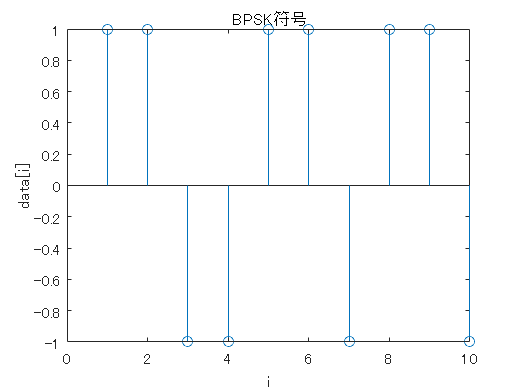

%TXD = logical(randi([0, 1], [1, N]))   %送信データ(ランダム)
t  = 0:Ts:(numel(TXD)-1)*Td;            %離散時間[s]

%信号空間ダイアグラムへのマッピング
BPSK(TXD==0) = A;
BPSK(TXD==1) = -A;
stem(BPSK)
xlabel('i');
ylabel('data[i]');
title('BPSK符号');

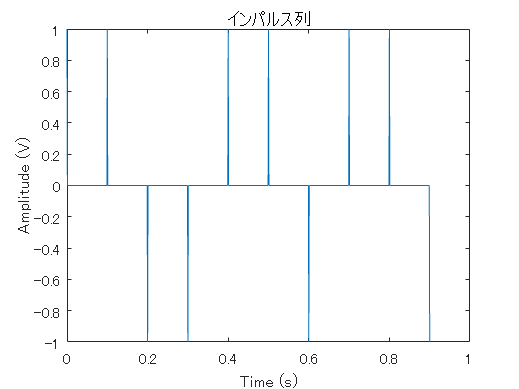


%インパルス列作成
i = 1;
impulse = zeros(1,numel(t));
for data = BPSK
    impulse(i) = data;
    i = i + Fs/Fd;
end
plot(t,impulse);
xlabel('Time (s)');
ylabel('Amplitude (V)');
title('インパルス列');

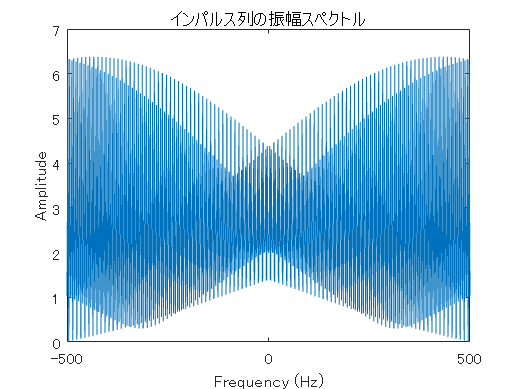

f_impulse = linspace(-Fs/2,Fs/2,numel(t));
plot(f_impulse,abs(fftshift(fft(impulse))));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('My Title');
title('インパルス列の振幅スペクトル');


%フィルタのインパルス応答を計算
k = 50;%フィルタインパルス応答の打ち切り時間調整
tf = -Td*k:Ts:Td*k-Ts; %フィルタインパルス応答の時間列
h = (1/Td).*sinc(tf/Td);

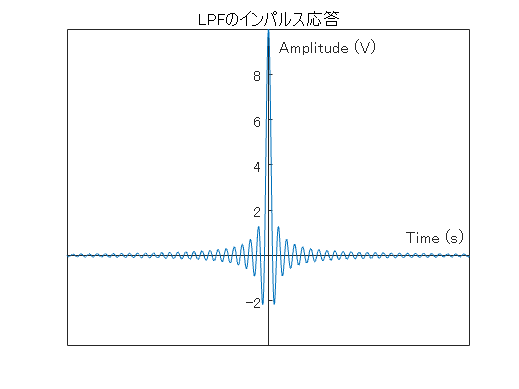


plot(tf,h);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
xlabel('Time (s)');
ylabel('Amplitude (V)');
title('LPFのインパルス応答');

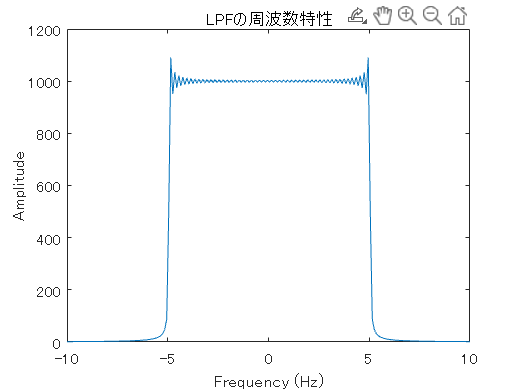

f_h = linspace(-Fs/2,Fs/2,numel(tf));
plot(f_h,abs(fftshift(fft(h))));
xlim([-1/Td 1/Td]);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('My Title');
title('LPFの周波数特性');

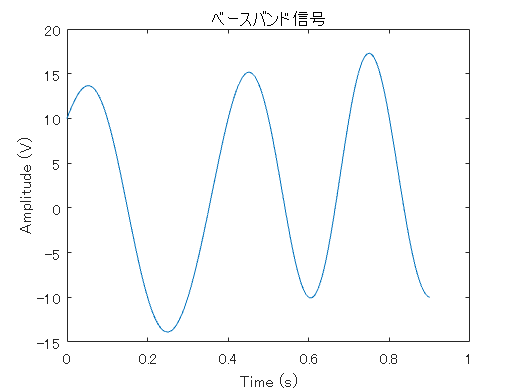


%インパルス列をフィルタに通過させる
impulse_LPF = conv(impulse,h);
delay = numel(h)/2; %フィルタの遅延量
impulse_LPF(1:delay) = []; %先頭の遅延分を削除
impulse_LPF = impulse_LPF(1:numel(t)); %後ろの遅延分を削除
plot(t,impulse_LPF);
xlabel('Time (s)');
ylabel('Amplitude (V)');
title('ベースバンド信号');

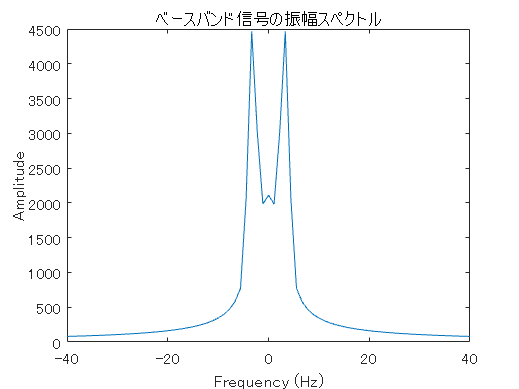

f = linspace(-Fs/2,Fs/2,numel(t));
plot(f,abs(fftshift(fft(impulse_LPF))));
xlim([-4/Td 4/Td]);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('ベースバンド信号の振幅スペクトル');

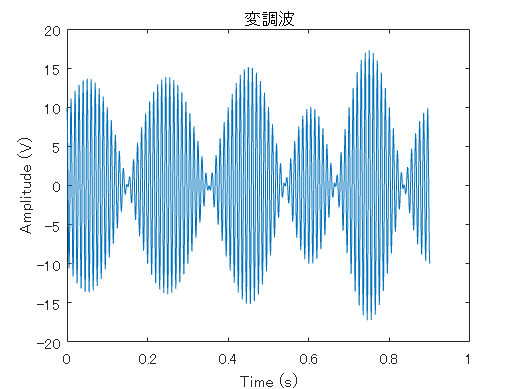


%インパルス列を搬送波に乗せる
carrier = cos(2*pi*Fc*t); %搬送波
s = impulse_LPF.*carrier;
plot(t,s);
xlabel('Time (s)');
ylabel('Amplitude (V)');
title('変調波');

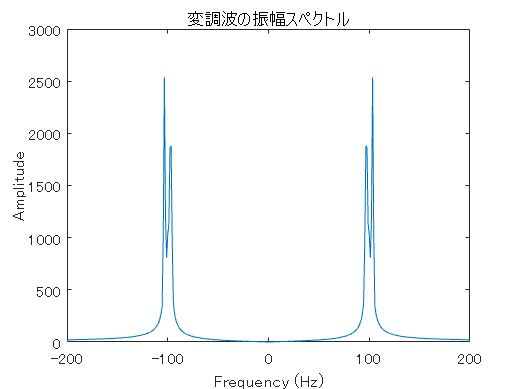

plot(f,abs(fftshift(fft(s))));
xlim([-2*Fc 2*Fc]);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('変調波の振幅スペクトル');

## ノイズ付加

%noisePower = 10000; %ノイズ電力
%r = s + normrnd(0,sqrt(noisePower),[1,numel(s)]);
snr = 100;
r = awgn(s,snr);

## 受信側

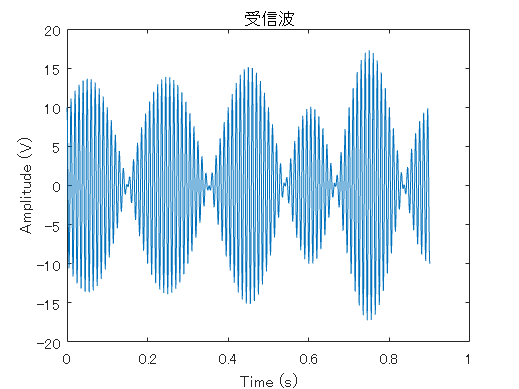

plot(t,r);
xlabel('Time (s)');
ylabel('Amplitude (V)');
title('受信波');

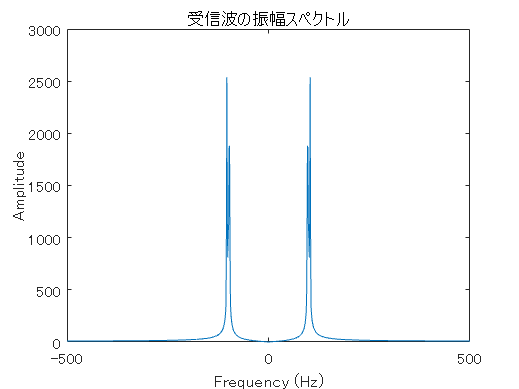

plot(f,abs(fftshift(fft(r))));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('受信波の振幅スペクトル');

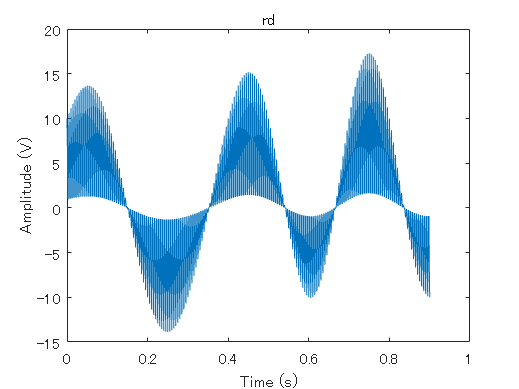


%同期検波
rd = r.*carrier; %受信波と基準信号と掛ける
plot(t,rd);
xlabel('Time (s)');
ylabel('Amplitude (V)');
title('rd');

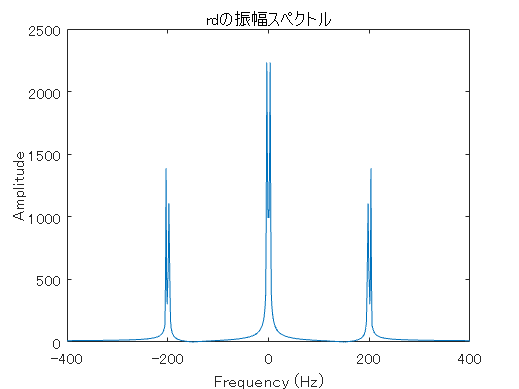

plot(f,abs(fftshift(fft(rd))));
xlim([-4*Fc 4*Fc]);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('rdの振幅スペクトル');

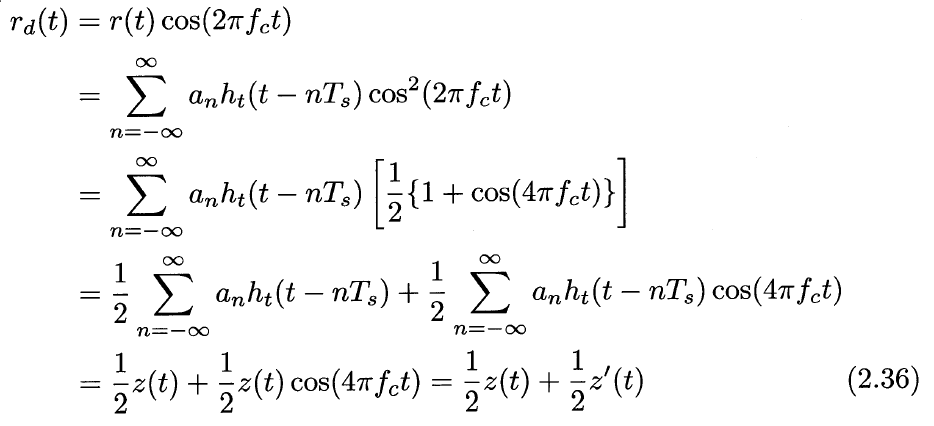

%高調波を除去
%フィルタのインパルス応答を計算（送信側のLPFと同じ）
k = 50; %フィルタインパルス応答の打ち切り時間調整
tf = -k*Td:Ts:Td*k-Ts;        %フィルタインパルス応答の時間列
h = (1/Td).*sinc(tf/Td);
plot(tf,h);
xlabel('Time (s)');
ylabel('Amplitude (V)');
title('LPFのインパルス応答');
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

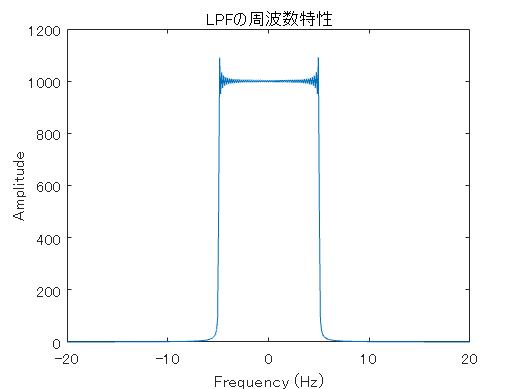

f_h = linspace(-Fs/2,Fs/2,numel(tf));
plot(f_h,abs(fftshift(fft(h))));
xlim([-2/Td 2/Td]);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('LPFの周波数特性');

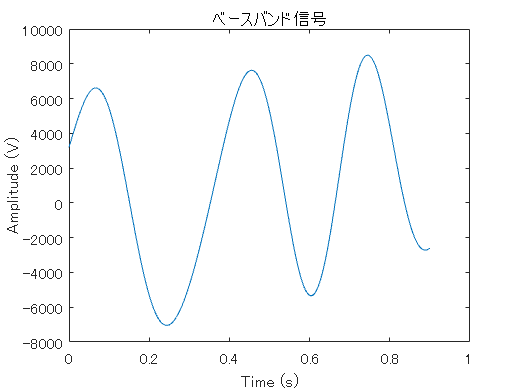


%rdをフィルタに通過させる
rd_LPF = conv(rd,h);
delay = numel(h)/2;             %フィルタの遅延量
rd_LPF(1:delay) = [];           %先頭の遅延分を削除
rd_LPF = rd_LPF(1:numel(t));    %後ろの遅延分を削除
plot(t,rd_LPF);
xlabel('Time (s)');
ylabel('Amplitude (V)');
title('ベースバンド信号');

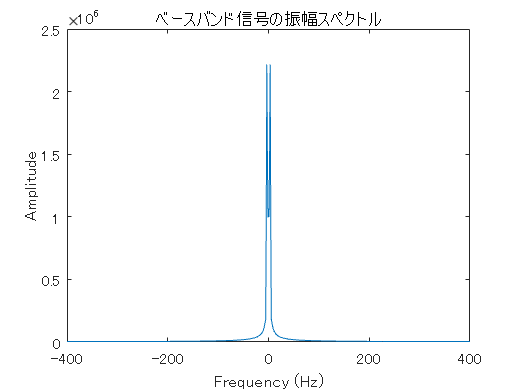

plot(f,abs(fftshift(fft(rd_LPF))));
xlim([-4*Fc 4*Fc]);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('ベースバンド信号の振幅スペクトル');


%ビット判定（符号変換）
RXD = zeros(1,numel(TXD));
j = 1;
for i = 1:numel(TXD)
    if  rd_LPF(j)>0
        RXD(i) = 0;
    else
        RXD(i) = 1;
    end
    j = j + Fs/Fd;
end

RXD %受信ディジタル信号

RXD =      0     0     1     1     0     0     1     0     0     1


## BER計算

error = 0;
for i = 1:numel(TXD)
    if RXD(i) ~= TXD(i)
        error = error + 1;
    end
end

error

error = 0

BER = error./numel(TXD)

BER = 0